# **Aircraft 6DOF Simulation - Handling Qualities**

**by Linzhe Wang,    Sep 15, 2022**

The program computes the 6DOF nonlinear dynamics model and integrates it with FlightGear to provide real-time visualization. The Research Civil Aircraft Model (RCAM) aerodynamic data is used as a test case to validate the output states ($X^T =\left\lbrack U\;\;V\;\;W\;\;\phi \;\;\theta \;\;\psi \;\;P\;\;Q\;\;R\;\;P_N \;\;P_E \;\;h\right\rbrack$) of the 6DOF program. The Simulink model utilizes the Model Linearizer function to determine steady-state conditions and linearize the dynamics model at the trim points. The program also determines flying qualities for longitudinal and lateral-directional motions, where the control inputs are ailerons, elevator, rudder, and throttle position of engines 1 and 2. 

## **Background Infomation**

Reference: 

- "Aircraft Control & Simulation", Stevens and Lewis

- "Aircraft Stability and Automatic Control", Robert C. Nelson

- "Robust Flight Control Design Challenge Problem Formulation and Manual", GARTEUR

### **Aerodynamic Forces**

drag,    $D=\bar{q} \;S\;C_D$

lift,    $L=\bar{q} \;S\;C_L$

sideforce,    $Y=\bar{q\;} \;S\;C_Y$

rolling moment,    $\bar{\;L} =\bar{\;q} \;S\;b\;C_l$

pitching moment,    $M=\bar{\;q} \;S\;\bar{c} \;C_M$

yawing moment,    $N=\bar{\;q} \;S\;b\;C_N$

total force in x (body-axes),    ${F_x }_{\textrm{Aero}} =L\;\sin \;\alpha -D\;\cos \;\alpha \;\cos \;\beta -Y\;\cos \;\alpha \;\sin \;\beta$

total force in y  (body-axes),    ${F_y }_{\textrm{Aero}} =-D\;\sin \;\beta +Y\;\cos \;\beta$

total force in z  (body-axes),    ${F_z }_{\textrm{Aero}} =-L\;\cos \;\alpha -D\;\sin \;\alpha \;\cos \;\beta -Y\;\sin \;\alpha \;\sin \;\beta$

### **The Nonlinear Aircraft Model**

state vector, $X^T =\left\lbrack U\;\;V\;\;W\;\;\phi \;\;\theta \;\;\psi \;\;P\;\;Q\;\;R\;\;P_N \;\;P_E \;\;h\right\rbrack$

#### Force Equations


$$\dot{U} =\textrm{RV}-\textrm{QW}-g_0^{\prime } \;\sin \;\theta +\frac{F_x }{m}$$



$$\dot{V} =-\textrm{RU}+\textrm{PW}+g_0^{\prime } \;\sin \;\phi \;\cos \;\theta +\frac{F_y }{m}$$



$$\dot{W} =\textrm{QU}-\textrm{PV}+g_0^{\prime } \;\cos \;\phi \;\cos \;\theta +\frac{F_z }{m}$$


#### Kinematic Equations


$$\dot{\phi} =P+\tan \;\theta \;\left(Q\;\sin \;\phi +R\;\cos \;\phi \right)$$



$$\dot{\theta} =Q\;\cos \;\phi -R\;\sin \;\phi$$



$$\dot{\psi} =\frac{Q\;\sin \;\phi +R\;\cos \;\phi }{\cos \;\theta }$$


#### Moment Equations

$J=\left\lbrack \begin{array}{ccc}
J_x  & 0 & -J_{\textrm{xz}} \\
0 & J_y  & 0\\
-J_{\textrm{xz}}  & 0 & J_z 
\end{array}\right\rbrack$,    $\Gamma =J_x J_z -J_{\textrm{xz}}^2$

$\Gamma c_1 =\left(J_y -J_z \right)J_z -J_{\textrm{xz}}^2$,    $\Gamma c_2 =\left(J_x -J_y +J_z \right)J_{\textrm{xz}}$

$\Gamma c_3 =J_z$,    $\Gamma c_4 =J_{\textrm{xz}}$

$c_5 =\frac{J_z -J_x }{J_y }$,    $c_6 =\frac{J_{\textrm{xz}} }{J_y }$

$c_7 =\frac{1}{J_y }$,    $\Gamma c_8 =J_x \left(J_x -J_y \right)+J_{\textrm{xz}}^2$


$$\Gamma c_9 =J_x$$



$$\dot{P} =\left(c_1 R+c_2 P\right)\;Q+c_3 \bar{L} +c_4 N$$



$$\dot{Q} =c_5 \textrm{PR}-c_6 \;\left(P^2 -R^2 \right)+c_7 M$$



$$\dot{R} =\left(c_8 P-c_2 R\right)\;Q+c_4 \bar{L} +c_9 N\;$$


#### **Navigation Equations**


$$\dot{P} N=U\;\cos \;\theta \;\cos \;\psi +V\;\left(-\cos \;\phi \;\sin \;\psi +\sin \;\phi \;\sin \;\theta \;\cos \;\psi \right)+W\;\left(\sin \;\phi \;\sin \;\psi +\cos \;\phi \;\sin \;\theta \;\cos \;\psi \right)$$



$$\dot{P} E=U\;\cos \;\theta \;\sin \;\psi +V\;\left(\cos \;\phi \;\cos \;\psi +\sin \;\phi \;\sin \;\theta \;\sin \;\psi \right)+W\;\left(-\sin \;\phi \;\cos \;\psi +\cos \;\phi \;\sin \;\theta \;\sin \;\psi \right)$$



$$\dot{h} =U\;\sin \;\theta -V\;\sin \;\phi \;\cos \;\theta -W\;\cos \;\phi \;\cos \;\theta$$


#### **Steady-State Conditions**


$$\dot{P} ,\dot{Q} ,\dot{R} ,\dot{U} ,\dot{V} ,\dot{W} \;\left(\textrm{or}\;\dot{V_T } ,\dot{\beta} ,\dot{\alpha} \right)=0,\;U=\textrm{const}$$


steady wings-level flight:    $\phi ,\dot{\phi} ,\dot{\theta} ,\dot{\psi} =0,\;\;\left(P,Q,R=0\right)$

steady turning flight:    $\dot{\phi} ,\dot{\theta} =0,\;\;\dot{\psi} =\textrm{turn}\;\textrm{rate}$

steady pull up:    $\phi ,\dot{\phi} ,\dot{\psi} =0,\;\;\dot{\theta} =\textrm{pull}\;\textrm{up}\;\textrm{rate}$

steady roll:    $\dot{\theta} ,\dot{\psi} =0,\;\;\dot{\phi} =\textrm{roll}\;\textrm{rate}$

**Aerodynamics for the Research Civil Aircraft Model (RCAM) - coded in Simulink **

$C_L =C_{L_{\textrm{wb}} } +C_{L_t }$,    $C_{L_{\textrm{wb}} } =5\ldotp 5\;\left(\alpha -\alpha_0 \right)$,    $C_{L_t } =\frac{S_t }{S}\;3\ldotp 1\;\alpha_t$,    $\alpha_0 =\frac{11\ldotp 5}{180}\;\pi$

$\alpha_t =\alpha -\varepsilon +\delta_E +1\ldotp 3\;\frac{q\;l_t }{V_{\textrm{tot}} }$,    $\varepsilon =\frac{d\varepsilon }{d\alpha }\;\left(\alpha -\alpha_0 \right)$,    $\frac{d\varepsilon }{d\alpha }=0\ldotp 25$

$C_D =0\ldotp 13+0\ldotp 07\;{\left(C_{L_{\textrm{wb}} } -0\ldotp 45\right)}^2$,    $C_Y =-1\ldotp 6\;\beta +0\ldotp 24\;\delta_R$


$$\left\lbrack \begin{array}{c}
C_l \\
C_m \\
C_n 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
-1\ldotp 4\;\beta \\
-0\ldotp 59-3\ldotp 1\;\frac{S_t {\;l}_t }{S\;l}\;\left(\alpha -\epsilon \right)\\
\left(1-\alpha \;\frac{180}{15\pi }\right)\beta 
\end{array}\right\rbrack +\left\lbrack \begin{array}{ccc}
-11 & 0 & 5\\
0 & -4\ldotp 03\;\frac{S_t \;l_t^2 }{S\;l^2 } & 0\\
1\ldotp 7 & 0 & -11\ldotp 5
\end{array}\right\rbrack \;\frac{l}{V_{\textrm{tot}} }\;\left\lbrack \begin{array}{c}
P\\
Q\\
R
\end{array}\right\rbrack +\left\lbrack \begin{array}{ccc}
-0\ldotp 6 & 0 & 0\ldotp 22\\
0 & -3\ldotp 1\;\frac{S_t \;l_t }{S\;l} & 0\\
0 & 0 & -0\ldotp 63
\end{array}\right\rbrack \;\left\lbrack \begin{array}{c}
\delta_A \\
\delta_E \\
\delta_R 
\end{array}\right\rbrack$$


#### **RCAM Engine Model**

$F=\left\lbrack \begin{array}{c}
\delta_{\textrm{THi}} \;\textrm{mg}\\
0\\
0
\end{array}\right\rbrack ,\;\left(i=1,2\right)$,    engines thrust vector is aligned along the x-body axis pointing forward 


$$M=\left\lbrack \begin{array}{c}
X_{\textrm{CG}} -X_{\textrm{APTi}} \\
Y_{\textrm{APTi}} -Y_{\textrm{CG}} \\
Z_{\textrm{CG}} -Z_{\textrm{APTi}} 
\end{array}\right\rbrack \;x\;\left\lbrack \begin{array}{c}
\delta_{\textrm{THi}} \;\textrm{mg}\\
0\\
0
\end{array}\right\rbrack$$


#### **Gravity Model **

WGS 84 model (function of geodetic latitude, longitude, and altitude)

#### Atmosphere Model

COESA Atmosphere Model (function of altitude)

## **Simulation Part**

**Aircraft Config**

clc;
clear;
close all;
% airframe data
LT = 24.8;  % distance between CoG and the aero centre of the tail (m)
S = 260; % wing planform area (m^2)
ST = 64;    % tail unit planform area (m^2)
cbar = 6.6; % mean aero chord (m)

% aircraft inertia tensor
mass = 120000;   % kg
Jx = mass * 40.07;    % kg m^2
Jxz = mass * -2.0923;    % kg m^2
Jy = mass * 64;   % kg m^2
Jz = mass * 99.92;    % kg m^2
gamma = Jx * Jz - Jxz^2;
c1 = ((Jy - Jz) * Jz - Jxz^2) / gamma;
c2 = ((Jx - Jy + Jz) * Jxz) / gamma;
c3 = Jz / gamma;
c4 = Jxz / gamma;
c5 = (Jz - Jx) / Jy;
c6 = Jxz / Jy;
c7 = 1 / Jy;
c8 = (Jx * (Jx - Jy) + Jxz^2) / gamma;
c9 = Jx / gamma;
c = [c1 c2 c3 c4 c5 c6 c7 c8 c9];

cg = [0.23 * cbar;  % x (m)
      0.0  * cbar;  % y (m)
      0.1  * cbar]; % z (m)

ac = [0.12 * cbar; % x pos of AC in Fm (m)
      0; % y pos of AC in Fm (m)
      0]; % z pos of AC in Fm (m)

% engine parameters
Xapt1 = 0;  % x pos - point of thrust of engine1 in body-axes w.r.t Cog (m)
Yapt1 = -7.94;   % y pos - point of thrust of engine1 in body-axes w.r.t Cog (m)
Zapt1 = -1.9;    % z pos - point of thrust of engine1 in body-axes w.r.t Cog (m)
Xapt2 = 0;  % x pos - point of thrust of engine2 in body-axes w.r.t Cog (m)
Yapt2 = 7.94;   % y pos - point of thrust of engine2 in body-axes w.r.t Cog (m)
Zapt2 = -1.9;    % z pos - point of thrust of engine2 in body-axes w.r.t Cog (m)

% engine moment arm
engArm1 = [cg(1) - Xapt1;
           Yapt1 - cg(2);
           cg(3) - Zapt1];

engArm2 = [cg(1) - Xapt2;
           Yapt2 - cg(2);
           cg(3) - Zapt2];

% Aero 
alpha0 = -11.5 * pi/180;  % alpha at which the lift becomes zero (rad)
a0 = 15.212;    % coefficient of alpha^0
a1 = -155.2;    % coefficient of alpha^1
a2 = 609.2;     % coefficient of alpha^2
a3 = -768.5;    % coefficient of alpha^3
alpha_stall = 14.5 * (pi/180);  % alpha where lift slope changes to non-linear
CLa = 5.5;    % slope CLa
depsilon = 0.25;    % delta_eps / delta_alpha

% control saturations
delta_aileronMin = deg2rad(-25);    % (rad)
delta_aileronMax = deg2rad(25); % (rad)

delta_elevatorMin = deg2rad(-25);   % (rad)
delta_elevatorMax = deg2rad(10);    % (rad)

delta_rudderMin = deg2rad(-30); % (rad)
delta_rudderMax = deg2rad(30);  % (rad)

delta_thrustMin = 0.5 * pi/180; 
delta_thrustMax = 1 * pi/180;

rising_slew_rate = 1.6; % rate limit for thrust 
falling_slew_rate = -1.6;   % rate limit for thrust

**FlightGear Environment (Geodetic Position)**

Lon0 = deg2rad(LonDeg(122,23,23.9172));  % deg
Lat0 = deg2rad(LatDeg(37,36,54.8028));    % deg
h_ref = 5;  % reference altitude (m) 

**State Variable (initial guess)**

x = [85;    % U - velocity in body-axis x direction (m/s)
     0; % V - velocity in body-axis y direction (m/s)
     0; % W - velocity in body-axis z direction (m/s)
     0;   % phi - roll angle (rad)
     0; % theta - pitch angle (rad)
     0;   % psi - yaw (heading) angle (rad)
     0; % P - roll rate (rad/s)
     0; % Q - pitch rate (rad/s)
     0; % R - yaw rate (rad/s)
     0; % position north in geographic frame (m)
     0; % position east in geographic frame (m)
     0];    % altitude - pos z down (m)

**Control Input (initial guess)**

u = [0;     % aileron deflection (rad)
     0;     % elevator deflection (rad) positive z-axis pointing down
     0;     % rudder deflection (rad)
     0;  % throttle position of engine 1 (for value = pi/180, thrust/weight = 0.35)
     0]; % throttle position of engine 2 (for value = pi/180, thrust/weight = 0.35)

**Find Equilibrium Points (via Simulink Model Linearizer)**

Set the constraints on the states in the model, the defaults for all states are:

- Known = false,    SteadyState = true,    Min = - Inf,    Max = Inf,    dxMin = - Inf,    dxMax = Inf

model = 'Aircraft6DOFTrim'; % Specify the model name    
opspec = operspec(model);   % Create the operating point specification object

% State (1) - U
opspec.States(1).Known = true;
opspec.States(1).x = x(1);

% State (2) - V
opspec.States(2).x = x(2);

% State (3) - W
opspec.States(3).x = x(3);

% State (4) - phi
opspec.States(4).x = x(4);

% State (5) - theta
opspec.States(5).x = x(5);

% State (6) - psi
opspec.States(6).x = x(6);

% State (7) - P
opspec.States(7).x = x(7);

% State (8) - Q
opspec.States(8).x = x(8);

% State (9) - R
opspec.States(9).x = x(9);

% State (10) - Navigation Equation (ignored)
opspec.States(10).Known = [true;    % PN    
                           true;    % PE
                           true];   % h

opspec.States(10).SteadyState = [false; % PN
                                 false; % PE
                                 false];    % h

Set the constraints on the inputs/outputs in the model 

$U=\left\lbrack \delta_A \;\;\delta_E \;\;\delta_R \;\;\delta_{\textrm{Th1}} \;\;\delta_{\textrm{Th2}} \right\rbrack$,    inputs

$X=\left\lbrack U\;\;V\;\;W\;\;\phi \;\;\theta \;\;\psi \;\;P\;\;Q\;\;R\right\rbrack$,    outputs

- Known = false,    Min = - Inf,    Max = Inf

% Input (1) - aileron deflection
opspec.Inputs(1).Min = delta_aileronMin;
opspec.Inputs(1).Max = delta_aileronMax;
opspec.Inputs(1).u = u(1);

% Input (2) - elevator deflection
opspec.Inputs(2).Min = delta_elevatorMin;
opspec.Inputs(2).Max = delta_elevatorMax;
opspec.Inputs(2).u = u(2);

% Input (3) - rudder deflection 
opspec.Inputs(3).Min = delta_rudderMin;
opspec.Inputs(3).Max = delta_rudderMax;
opspec.Inputs(3).u = u(3);

% Input (4) - throttle position 1
opspec.Inputs(4).Min = delta_thrustMin;
opspec.Inputs(4).Max = delta_thrustMax;
opspec.Inputs(4).u = u(4);

% Input (5) - throttle position 2
opspec.Inputs(5).Min = delta_thrustMin;
opspec.Inputs(5).Max = delta_thrustMax;
opspec.Inputs(5).u = u(5);

% Output (1) - X

[trim_point] = findop(model,opspec) % Perform the operating point search.


 Operating point search report:
---------------------------------


opreport =  Operating point search report for the Model Aircraft6DOFTrim.
 (Time-Varying Components Evaluated at time t=0)

Operating point specifications were successfully met.
States: 
----------
    Min          x          Max        dxMin        dx         dxMax   
___________ ___________ ___________ ___________ ___________ ___________
                                                                       
(1.) U
    85          85          85           0      -3.7303e-14      0     
(2.) V
   -Inf     1.2279e-08      Inf          0      7.9773e-15       0     
(3.) W
   -Inf       1.3229        Inf          0      -3.0376e-13      

trim_point =  Operating point for the Model Aircraft6DOFTrim.
 (Time-Varying Components Evaluated at time t=0)

States: 
----------
     x     
___________
           
(1.) U
    85     
(2.) V
1.2279e-08 
(3.) W
  1.3229   
(4.) phi
2.8264e-07 
(5.) theta
 -0.11492  
(6.) psi
-9.0486e-

**Simulation Output (nonlinear)**

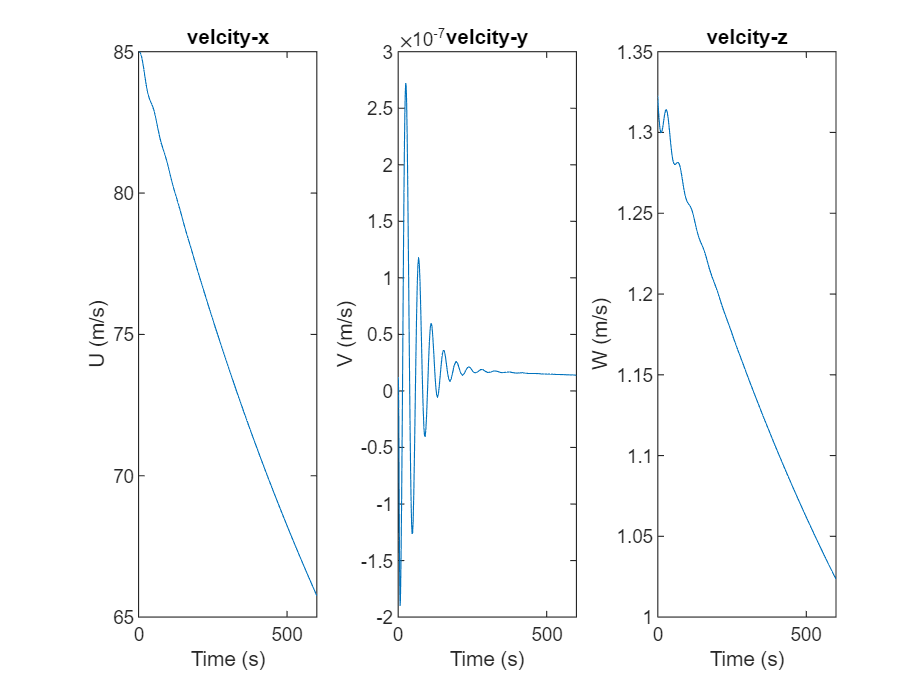

u = [trim_point.Inputs(1, 1).u;
     trim_point.Inputs(2, 1).u;
     trim_point.Inputs(3, 1).u;
     trim_point.Inputs(4, 1).u;
     trim_point.Inputs(5, 1).u];

x = [trim_point.States(1, 1).x; % U
     trim_point.States(2, 1).x; % V
     trim_point.States(3, 1).x; % W
     trim_point.States(4, 1).x; % phi
     trim_point.States(5, 1).x; % theta
     trim_point.States(6, 1).x; % psi   
     trim_point.States(7, 1).x; % P
     trim_point.States(8, 1).x; % Q
     trim_point.States(9, 1).x; % R
     trim_point.States(10, 1).x];    % PN PE h    

sim_time = 600;
sim('Aircraft6DOF',sim_time);
t_out = ans.states.time;
U = ans.states.signals.values(:,1); % m/s
V = ans.states.signals.values(:,2); % m/s
W = ans.states.signals.values(:,3); % m/s
phi = ans.states.signals.values(:,4); % rad
theta = ans.states.signals.values(:,5); % rad
psi = ans.states.signals.values(:,6); % rad
P = ans.states.signals.values(:,7); % rad/s
Q = ans.states.signals.values(:,8); % rad/s
R = ans.states.signals.values(:,9); % rad/s
PN = ans.states.signals.values(:,10); % m
PE = ans.states.signals.values(:,11); % m
h = ans.states.signals.values(:,12); % m
alpha = ans.states.signals.values(:,13); % rad
beta = ans.states.signals.values(:,14); % rad
mach = ans.states.signals.values(:,15); 
Nz = ans.states.signals.values(:,16); 

figure;
subplot(1,3,1)
plot(t_out,U);
title("velcity-x");
ylabel("U (m/s)");
xlabel("Time (s)");
subplot(1,3,2)
plot(t_out,V);
title("velcity-y");
ylabel("V (m/s)");
xlabel("Time (s)");
subplot(1,3,3)
plot(t_out,W);
title("velcity-z");
ylabel("W (m/s)");
xlabel("Time (s)");

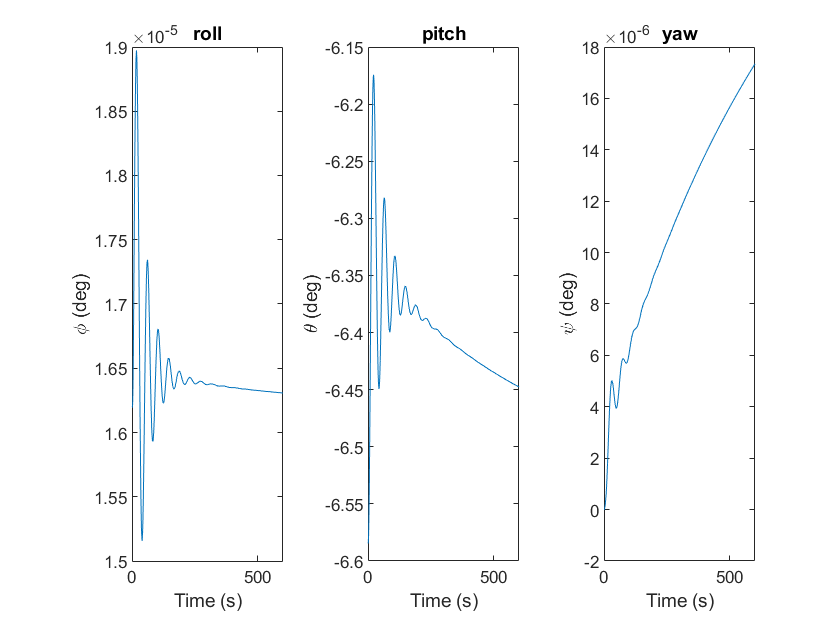

figure;
subplot(1,3,1)
plot(t_out,rad2deg(phi));
title("roll");
ylabel("\phi (deg)");
xlabel("Time (s)");
subplot(1,3,2)
plot(t_out,rad2deg(theta));
title("pitch");
ylabel("\theta (deg)");
xlabel("Time (s)");
subplot(1,3,3)
plot(t_out,rad2deg(psi));
title("yaw");
ylabel("\psi (deg)");
xlabel("Time (s)");

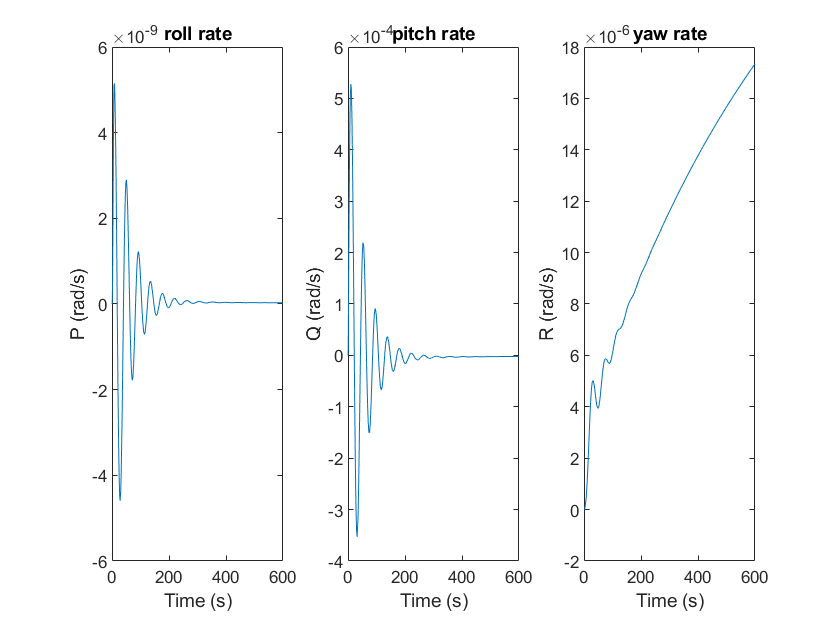

figure;
subplot(1,3,1)
plot(t_out,P);
title("roll rate");
ylabel("P (rad/s)");
xlabel("Time (s)");
subplot(1,3,2)
plot(t_out,Q);
title("pitch rate");
ylabel("Q (rad/s)");
xlabel("Time (s)");
subplot(1,3,3)
plot(t_out,rad2deg(psi));
title("yaw rate");
ylabel("R (rad/s)");
xlabel("Time (s)");

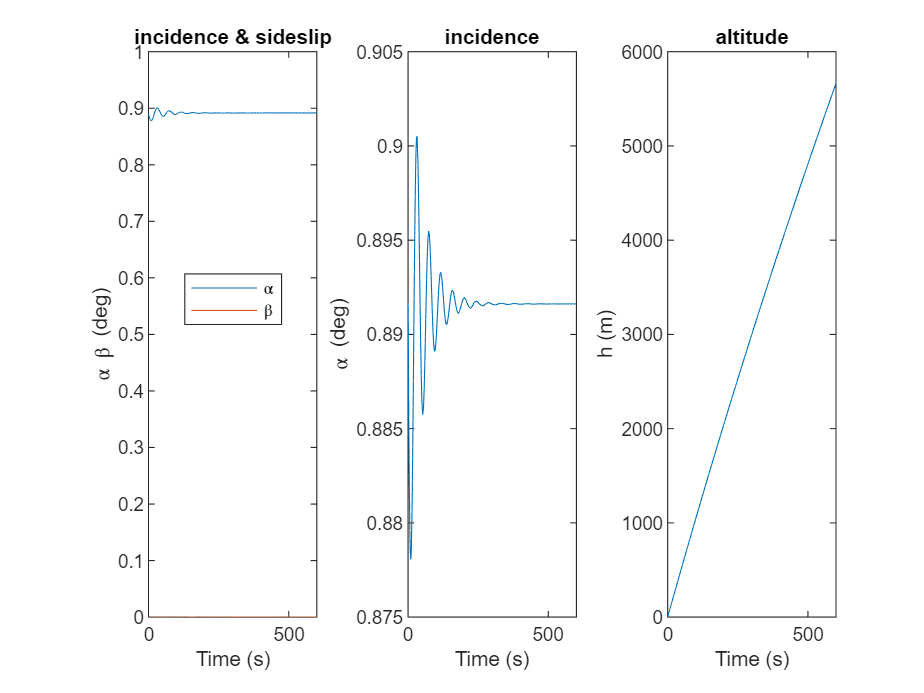

figure;
subplot(1,3,1)
plot(t_out,rad2deg(beta));
title("sideslip");
ylabel("\beta (deg)");
xlabel("Time (s)");
subplot(1,3,2)
plot(t_out,rad2deg(alpha));
title("incidence");
ylabel("\alpha (deg)");
xlabel("Time (s)");
subplot(1,3,3)
plot(t_out,-h);
title("altitude");
ylabel("h (m)");
xlabel("Time (s)");
subplot(1,3,1)
plot(t_out,rad2deg(alpha),t_out,rad2deg(beta));
title("incidence & sideslip");
legend("\alpha","\beta","location","best");
ylabel("\alpha \beta (deg)");
xlabel("Time (s)");

## **Dynamic Stability and Control**

All flight vehicles possess certain natural frequencies or motions when disturbed from their equilibrium flight.

### Second - Order Differential Equations

$m\;\frac{d^2 x}{{\textrm{dt}}^2 }+c\;\frac{\textrm{dx}}{\textrm{dt}}+\textrm{kx}=F\left(t\right)$ or $\frac{d^2 x}{{\textrm{dt}}^2 }+\frac{c}{m}\;\frac{\textrm{dx}}{\textrm{dt}}+\frac{k}{m}x=\frac{1}{m}F\left(t\right)$,$F\left(t\right)=0$ for homogeneous Eq 

$\lambda^2 +2\zeta \omega_n \lambda +\omega_n^2 =0$,    characteristic equation 

$\lambda_{1,2} =-\zeta \omega_n \pm {i\omega }_n \sqrt{1-\zeta^2 }$,    characteristic roots or eigenvalues of the system 

damping ratio: $\zeta =\frac{c}{2\sqrt{\textrm{km}}}$,    natural frequency: $\omega_n =\sqrt{\frac{k}{m}}$


$$\left\lbrack \begin{array}{ccc}
\mathbf{Magnitude}\;\mathbf{of}\;\mathbf{damping}\;\mathbf{ratio} & \mathbf{Type}\;\mathbf{of}\;\mathbf{root} & \mathbf{Time}\;\mathbf{response}\\
\zeta <-1 & \mathrm{Two}\;\mathrm{positive}\;\mathrm{real}\;\mathrm{distinct}\;\mathrm{roots} & \mathrm{Exponentially}\;\mathrm{growing}\;\mathrm{motion}\\
0>\zeta >-1 & \mathrm{Complex}\;\mathrm{roots}\;\mathrm{with}\;a\;\mathrm{positive}\;\mathrm{real}\;\mathrm{part} & \mathrm{Exponentially}\;\mathrm{growing}\;\mathrm{sinusoidal}\;\mathrm{motion}\\
\zeta =0 & \mathrm{Complex}\;\mathrm{roots}\;\mathrm{with}\;a\;\mathrm{real}\;\mathrm{part}\;0 & \mathrm{Undamped}\;\mathrm{sinusoidal}\;\mathrm{motion}\;\mathrm{Pure}\;\mathrm{harmonic}\;\mathrm{motion}\\
0<\zeta <1 & \mathrm{Complex}\;\mathrm{roots}\;\mathrm{with}\;a\;\mathrm{real}\;\mathrm{part}\;\mathrm{negative} & \mathrm{Underdamped}\;\mathrm{exponentially}\;\mathrm{decaying}\;\mathrm{sinusoidal}\;\mathrm{motion}\\
\zeta =1 & \mathrm{Two}\;\mathrm{negative}\;\mathrm{equal}\;\mathrm{real}\;\mathrm{roots} & \mathrm{Critically}\;\mathrm{damped}\;\mathrm{exponentially}\;\mathrm{decaying}\;\mathrm{motion}\\
\zeta >1 & \mathrm{Two}\;\mathrm{negative}\;\mathrm{distinct}\;\mathrm{real}\;\mathrm{roots} & \mathrm{Overdamped}\;\mathrm{exponentially}\;\mathrm{decaying}\;\mathrm{motion}
\end{array}\right\rbrack$$


### **Stick Fixed Longitudinal Motion**

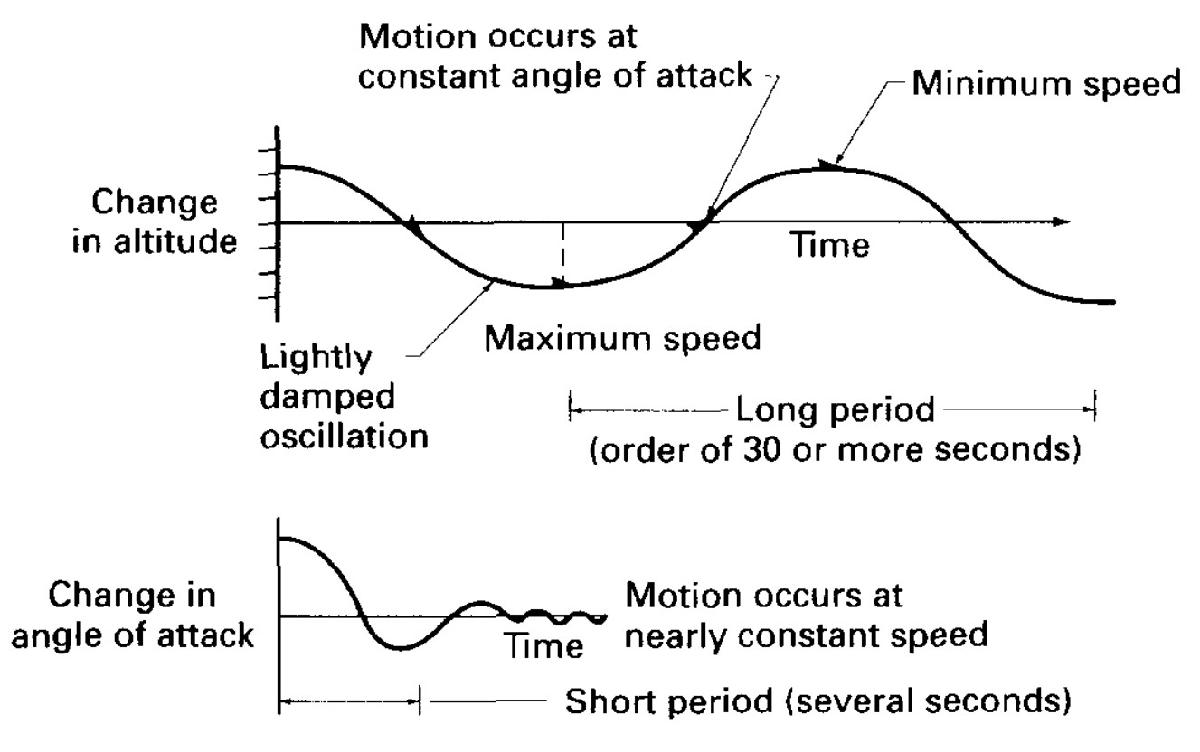


$$\dot{x} =\textrm{Ax}+\textrm{Bu}$$



$$\left\lbrack \begin{array}{c}
\Delta \dot{u} \\
\Delta \dot{w} \\
\Delta \dot{q} \\
\Delta \dot{\theta} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
X_u  & X_w  & 0 & -g\\
Z_u  & Z_w  & u_0  & 0\\
M_u +M_{\dot{w} } Z_u  & M_w +M_{\dot{w} } Z_w  & M_q +M_{\dot{w} } u_0  & 0\\
0 & 0 & 1 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\Delta u\\
\Delta w\\
\Delta q\\
\Delta \theta 
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
X_{\delta }  & X_{\delta_T } \\
Z_{\delta }  & Z_{\delta_T } \\
M_{\delta } +M_{\dot{w} } Z_{\delta }  & M_{\delta_T } +M_{\dot{w} } Z_{\delta_T } \\
0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\Delta \delta \\
\Delta \delta_T 
\end{array}\right\rbrack$$


$\Delta \delta$: aerodynamics    $\Delta \delta_T$: propulsive controls 

### **The Influence of Stability Derivatives on the Longitudinal Modes**


$$\left\lbrack \begin{array}{ccc}
\textrm{Stability}\;\textrm{derivative} & \textrm{Mode}\;\textrm{affected} & \textrm{How}\;\textrm{affected}\\
M_q +M_{\alpha }  & \textrm{Damping}\;\textrm{of}\;\textrm{short}\;\textrm{period} & \textrm{increase}\;M_q +M_{\alpha } =\textrm{increase}\;\textrm{damping}\\
M_{\alpha }  & \textrm{Frequency}\;\textrm{of}\;\textrm{short}\;\textrm{period} & \textrm{increase}\;M_{\alpha } \;\textrm{or}\;\textrm{static}\;\textrm{stability}=\textrm{increase}\;\textrm{frequency}\\
X_u  & \textrm{Damping}\;\textrm{of}\;\textrm{the}\;\textrm{phugoid} & \textrm{increase}\;X_u =\textrm{increase}\;\textrm{damping}\\
Z_u  & \textrm{Frequency}\;\textrm{of}\;\textrm{phugoid} & \textrm{increase}\;Z_u =\textrm{increase}\;\textrm{frequency}\;
\end{array}\right\rbrack$$


### MIL-F-8785C **Flying Qualities**

Level 1: Flying qualities clearly adequate for the mission flight phase

Corresponds with Cooper-Harper Scale values **1-3.5**

Level 2: Flying qualities adequate to accomplish the mission flight phase but with some increase in pilot workload and/or degradation in mission effectiveness or both

Corresponds with Cooper-Harper Scale values **3.5-6.5**

Level 3: Flying qualities such that the airplane can be controlled safely but pilot workload is excessive and/or mission effectiveness is inadequate or both

Corresponds with Cooper-Harper Scale values **6.5-9+**

### Pilot Opinion

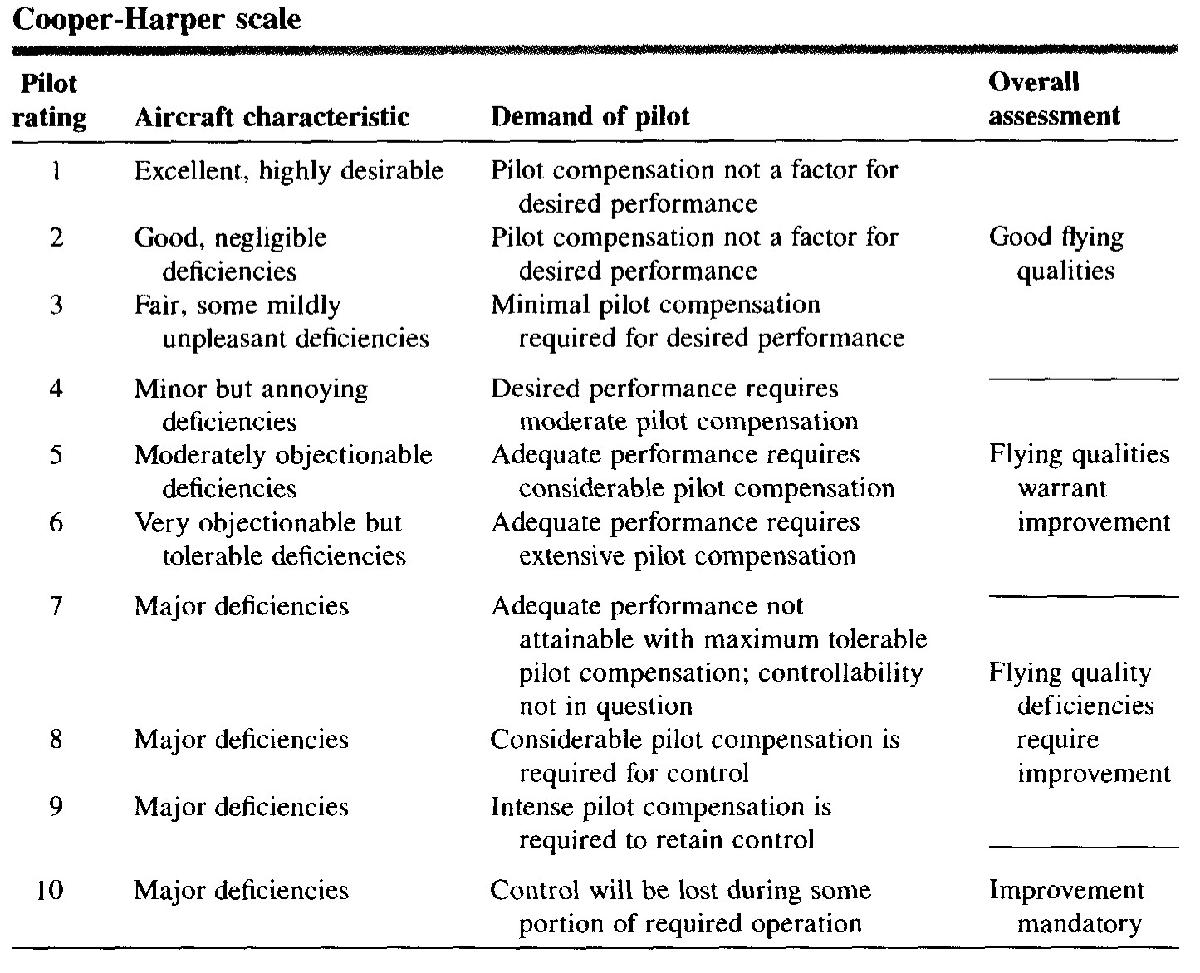

**Linearization (Linear-Time-Invariant State)**

An input perturbation is applied to the Aileron, Elevator, Rudder, and Throttle Command Input ports. 

Output measurements are taken for states *P*, *Q*, and *R* .

io = getlinio(model);   % Get the analysis I/Os from the model

op = operpoint('Aircraft6DOFTrim'); % Create the operating point variable op 

% Set the states in the model with trim condition
op.States(1).x = [trim_point.States(1, 1).x];    % U
op.States(2).x = [trim_point.States(2, 1).x];   % V
op.States(3).x = [trim_point.States(3, 1).x];   % W
op.States(4).x = [trim_point.States(4, 1).x];   % phi
op.States(5).x = [trim_point.States(5, 1).x];   % theta
op.States(6).x = [trim_point.States(6, 1).x];   % psi
op.States(7).x = [trim_point.States(7, 1).x];   % P
op.States(8).x = [trim_point.States(8, 1).x];   % Q
op.States(9).x = [trim_point.States(9, 1).x];   % R
op.States(10).x = [trim_point.States(10, 1).x];   % PN PE h

% Set the inputs in the model with trim input condition
op.Inputs(1).u = trim_point.Inputs(1, 1).u;    % aileron deflection
op.Inputs(2).u = trim_point.Inputs(2, 1).u;    % elevator deflection
op.Inputs(3).u = trim_point.Inputs(3, 1).u;    % rudder deflection 
op.Inputs(4).u = trim_point.Inputs(4, 1).u;   % throttle position 1
op.Inputs(5).u = trim_point.Inputs(5, 1).u;    % throttle position 2

aircraft_sys = linearize(model,io,op)   % Linearize the model

aircraft_sys =
 
  A = 
                   U           V
   U        -0.03536   3.229e-08
   V      -6.457e-08     -0.1995
   W         -0.2176   4.691e-10
   phi             0           0
   theta           0           0
   psi             0           0
   P      -6.054e-10    -0.02945
   Q        0.000202   -4.64e-14
   R       1.167e-08    0.008937
 
                   W         phi
   U         0.06018           0
   V      -1.014e-09       9.716
   W         -0.7066  -2.746e-06
   phi             0           0
   theta           0           0
   psi             0           0
   P      -9.207e-12           0
   Q        -0.03362           0
   R       1.776e-10           0
 
               theta         psi
   U          -9.716           0
   V        3.17e-07           0
   W           1.121           0
   phi    -2.223e-25  -6.426e-24
   theta           0   2.194e-25
   psi     2.549e-26   5.604e-23
   P               0           0
   Q               0           0
   R           

aircraft_sysTF = tf(aircraft_sys)  % transder function for the linearized system 

aircraft_sysTF =
 
  From input "AileronCmd" to output...
                                    
              -0.9488 s^8           
                                    
                      - 2.481 s^7   
                                    
                      - 5.56 s^6    
                                    
                      - 4.258 s^5   
                                    
                      - 3.043 s^4   
                                    
                      - 0.2321 s^3  
                                    
                      - 0.05908 s^2 
                                    
                      - 0.0006534 s 
                                    
                         + 6.017e-26
                                    
   P,Q,R(1):  ----------------------
                                    
              s^9 + 3.983 s^8       
                                    
                      + 9.467 s^7   
                                    
                 

B = table(aircraft_sys.B(1:9,1), aircraft_sys.B(1:9,2), aircraft_sys.B(1:9,3), ...
          aircraft_sys.B(1:9,4),aircraft_sys.B(1:9,5),...
          'RowNames',{'U','V','W','phi','theta','psi','P','Q','R'},...
          'VariableNames', {'aileron','elevator','rudder','throttle 1','throttle 2'})

B = 9×5 table
             aileron     elevator     rudder     throttle 1    throttle 2
             ________    ________    ________    __________    __________

    U               0    0.11388            0       9.7803        9.7803 
    V               0          0       2.3017            0             0 
    W               0    -7.3174            0            0             0 
    phi             0          0            0            0             0 
    theta           0          0            0            0             0 
    psi             0          0            0            0             0 
    P        -0.94884          0       0.4076    -0.040626      0.040626 
    Q        

The elevator has no effect on the lateral-directional states ($V,\phi ,\psi ,P,R$).  The effects of aileron and rudder controls on the longitudinal states are minimal.

**Reduce Combined State-space Model to Decoupled Longitudinal Model**

aircraft_sys_Lon = modred(aircraft_sys, [2,4,6,7,9], 'Truncate')    % eliminate extra states 

aircraft_sys_Lon =
 
  A = 
                 U         W
   U      -0.03536   0.06018
   W       -0.2176   -0.7066
   theta         0         0
   Q      0.000202  -0.03362
 
             theta         Q
   U        -9.716     -1.28
   W         1.121     82.22
   theta         0         1
   Q             0    -1.107
 
  B = 
           AileronCmd  ElevatorCmd
   U                0       0.1139
   W                0       -7.317
   theta            0            0
   Q                0        -2.92
 
            RudderCmd   ThrustCmd1
   U                0         9.78
   W                0            0
   theta            0            0
   Q                0       0.3912
 
           ThrustCmd2
   U             9.78
   W                0
   theta            0
   Q           0.3912
 
  C = 
                 U      W
   P,Q,R(1)      0      0
   P,Q,R(2)      0      0
   P,Q,R(3)      0      0
 
             theta      Q
   P,Q,R(1)      0      0
   P,Q,R(2)      0      1
   P,Q,R(3)   

aircraft_sys_LonTF = tf(aircraft_sys_Lon)   % transfer function for the linearized Longitudinal Motion

aircraft_sys_LonTF =
 
  From input "AileronCmd" to output...
   P,Q,R(1):  0
 
   P,Q,R(2):  0
 
   P,Q,R(3):  0
 
  From input "ElevatorCmd" to output...
   P,Q,R(1):  0
 
                                    
              -2.92 s^3 - 1.921 s^2 
                                    
                      - 0.1017 s    
                                    
                         - 7.563e-19
                                    
   P,Q,R(2):  ----------------------
                                    
              s^4 + 1.849 s^3       
                                    
                      + 3.625 s^2   
                                    
                      + 0.1881 s    
                                    
                           + 0.07379
                                    
 
   P,Q,R(3):  0
 
  From input "RudderCmd" to output...
   P,Q,R(1):  0
 
   P,Q,R(2):  0
 
   P,Q,R(3):  0
 
  From input "ThrustCmd1" to output...
   P,Q,R(1):  0
 
                            

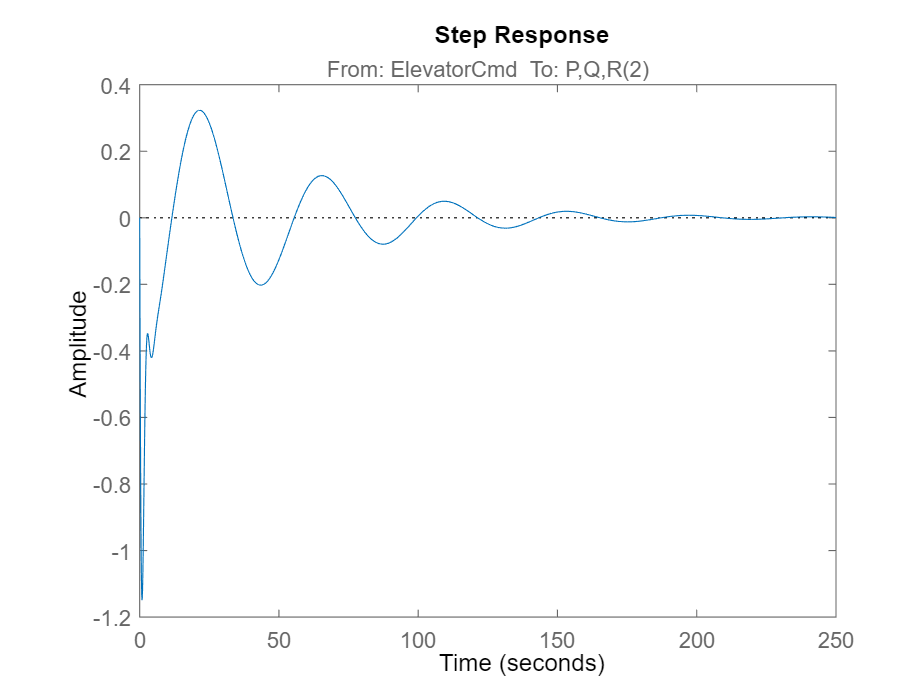

figure;
stepplot(aircraft_sys_Lon(2,2))

**Solve Characteristic Equation (Longitudinal)**


$$\lambda_{\textrm{sp}} =\zeta_{\textrm{sp}} \;\omega_{n_{\textrm{sp}} } \pm i\omega_{n_{\textrm{sp}} } \;\sqrt{1-\zeta_{\textrm{sp}}^2 }$$
   

**Short-Period** Damping Ratio: $\zeta_{\textrm{sp}} =\sqrt{\frac{1}{1+\frac{\omega_{\textrm{sp}} }{\eta_{\textrm{sp}} }}}$    Short-Period Undamped Natural Frequency: $\omega_{n_{\textrm{sp}} } =-\frac{\eta_{\textrm{sp}} }{\zeta_{\textrm{sp}} }$    Time to Double: $T_{2_{\textrm{sp}} } =\frac{\ln \left(2\right)}{-\zeta_{\textrm{sp}\;} \omega_{\textrm{sp}} }$


$$\lambda_{\textrm{ph}} =\zeta_{\textrm{ph}} \;\omega_{n_{\textrm{ph}} } \pm i\omega_{n_{\textrm{ph}} } \;\sqrt{1-\zeta_{\textrm{ph}}^2 }$$
 

**Phugoid** Damping Ratio: $\zeta_{\textrm{ph}} =\sqrt{\frac{1}{1+\frac{\omega_{\textrm{ph}} }{\eta_{\textrm{ph}} }}}$    Phugoid Undamped Natural Frequency: $\omega_{n_{\textrm{ph}} } =-\frac{\eta_{\textrm{ph}} }{\zeta_{\textrm{ph}} }$    Time to Double: $T_{2_{ph} } =\frac{\ln \left(2\right)}{-\zeta_{ph} {\;\omega }_{ph} }$

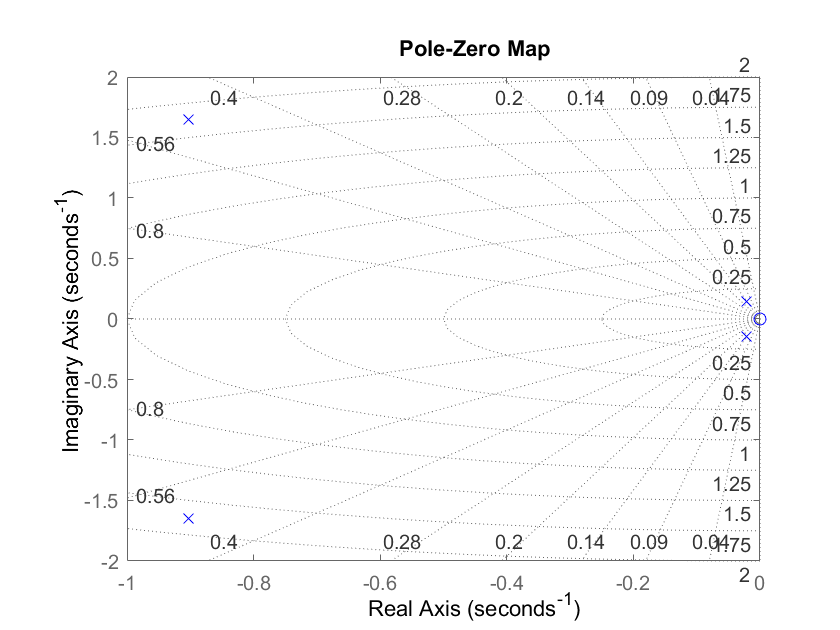

pzplot(aircraft_sys_Lon,'b'); 
grid on;

eigen_A_lon = eig(aircraft_sys_Lon);

The complex conjugate pair with the higher frequency of oscillation (greater imaginary part) is the short-period mode. The complex conjugate pair with the lower frequency is the long-period mode, or phugoid mode

phugoid = [eigen_A_lon(3);eigen_A_lon(4)]

phugoid =   -0.0213 + 0.1431i
  -0.0213 - 0.1431i


short_period = [eigen_A_lon(1);eigen_A_lon(2)]

short_period =   -0.9034 + 1.6464i
  -0.9034 - 1.6464i


**Longitudinal Flying Qualities**

Phugoid Mode:

Level 1    $\zeta >0\ldotp 04$

Level 2    $\zeta >0$

Level 3    $T_2 >55\;s$

Short Period Mode (Category B):


$$\left\lbrack \begin{array}{ccc}
 & \zeta_{\textrm{sp}}  & \zeta_{\textrm{sp}} \\
\textrm{Level} & \min  & \max \\
1 & 0\ldotp 3 & 2\ldotp 0\\
2 & 0\ldotp 2 & 2\ldotp 0\\
3 & 0\ldotp 15 & -
\end{array}\right\rbrack$$


ph_zeta = sqrt(1/(1+(imag(phugoid(1))/real(phugoid(1)))^2));
ph_omega_n = -real(phugoid(1))/ph_zeta;
ph_T2 = log(2)/(-ph_zeta * ph_omega_n);
fprintf(['phugoid damping ratio = %f\n' ...
         'phugoid undamped natural frequency = %f (rad/s)\n'...
         'time to double phugoid = %f (s)'],ph_zeta,ph_omega_n,ph_T2);

phugoid damping ratio = 0.147341
phugoid undamped natural frequency = 0.144652 (rad/s)
time to double phugoid = -32.522068 (s)

sp_zeta = sqrt(1/(1+(imag(short_period(1))/real(short_period(1)))^2));
sp_omega_n = -real(short_period(1))/sp_zeta;
sp_T2 = log(2)/(-sp_zeta * sp_omega_n);
fprintf(['short period damping ratio = %f\n' ...
         'short period undamped natural frequency = %f (rad/s)\n'...
         'time to double short period = %f (s)'],sp_zeta,sp_omega_n,sp_T2);

short period damping ratio = 0.481051
short period undamped natural frequency = 1.877960 (rad/s)
time to double short period = -0.767269 (s)

**Compare Phugoid Response to Short-period Response**


$$f(t) = (\omega_{n}/\sqrt{1-\zeta^{2}}) e^{-\zeta{\omega}t}sin(\omega_{n}\sqrt{1-\zeta^{2}}t )$$


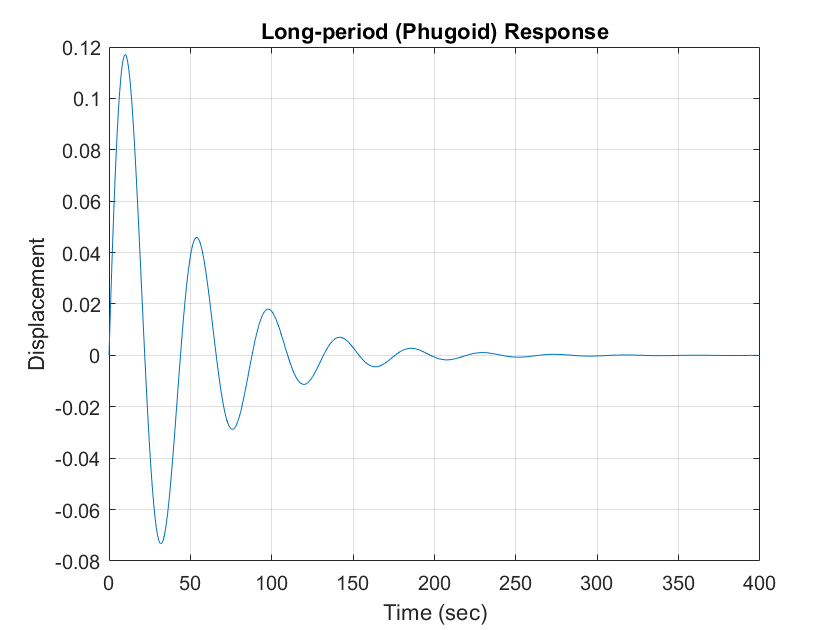

t = 0:.1:400;
figure;
plot(t, ph_omega_n/sqrt(1-ph_zeta^2).*exp(-ph_zeta*ph_omega_n*t).*sin(ph_omega_n*sqrt(1-ph_zeta^2)*t))
ylabel('Displacement'); xlabel('Time (sec)'); title('Long-period (Phugoid) Response'); grid on;

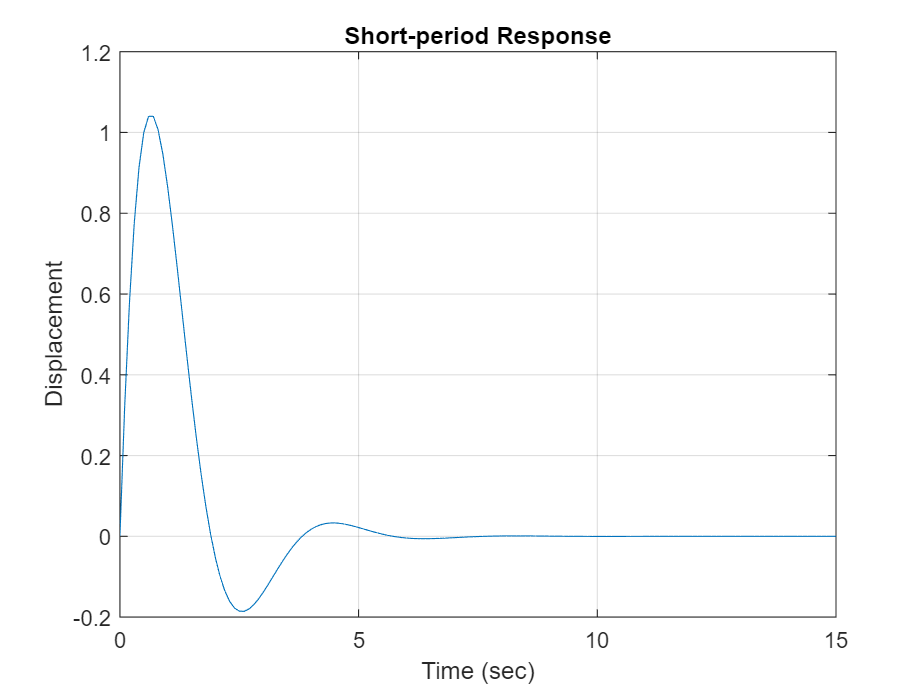

t = 0:.1:15;
figure;
plot(t, sp_omega_n/sqrt(1-sp_zeta^2).*exp(-sp_zeta*sp_omega_n*t).*sin(sp_omega_n*sqrt(1-sp_zeta^2)*t))
ylabel('Displacement'); xlabel('Time (sec)'); title('Short-period Response'); grid on;

### **Stick Fixed Lateral-Directional Motion**


$$\dot{x} =\textrm{Ax}+\textrm{Bu}$$


$A=\left\lbrack \begin{array}{cccc}
Y_v  & Y_p  & -\left(u_0 -Y_r \right) & g\;\cos \theta_0 \\
L_v^* +\frac{I_{\textrm{xz}} }{I_x }N_v^*  & L_P^* +\frac{I_{\textrm{xz}} }{I_x }N_P^*  & L_r^* +\frac{I_{\textrm{xz}} }{I_x }N_r^*  & 0\\
N_v^* +\frac{I_{\textrm{xz}} }{I_z }L_v^*  & N_p^* +\frac{I_{\textrm{xz}} }{I_z }L_p^*  & N_r^* +\frac{I_{\textrm{xz}} }{I_z }L_r^*  & 0\\
0 & 1 & 0 & 0
\end{array}\right\rbrack$,    $L_v^* =\frac{L_v }{1-\left(\frac{I_{\textrm{xz}}^2 }{I_x I_z }\right)}$,    $N_v^* =\frac{N_v }{1-\left(\frac{I_{\textrm{xz}}^2 }{I_x I_z }\right)}$

$B=\left\lbrack \begin{array}{cc}
0 & Y_{\delta_r } \\
L_{\delta_a }^* +\frac{I_{\textrm{xz}} }{I_x }N_{\delta_a }^*  & L_{\delta_r }^* +\frac{I_{\textrm{xz}} }{I_x }N_{\delta_r }^* \\
N_{\delta_a }^* +\frac{I_{\textrm{xz}} }{I_z }L_{\delta_a }^*  & N_{\delta_r }^* +\frac{I_{\textrm{xz}} }{I_z }L_{\delta_r }^* \\
0 & 0
\end{array}\right\rbrack$,    $x=\left\lbrack \begin{array}{c}
\Delta v\\
\Delta p\\
\Delta r\\
\Delta \phi 
\end{array}\right\rbrack$,    $u=\left\lbrack \begin{array}{c}
\Delta \delta_a \\
\Delta \delta_r 
\end{array}\right\rbrack$

### **Lateral Flying Qualities **

Spiral Mode (Minimum time to double amplitude)


$$\left\lbrack \begin{array}{ccccc}
\mathbf{Class} & \mathbf{Category} & \mathbf{Level}\;1\;\left(s\right) & \mathbf{Level}\;2\;\left(s\right) & \mathbf{Level}\;3\;\left(s\right)\\
\mathrm{I}\;\mathrm{and}\;\mathrm{IV} & \mathrm{A} & 12\; & 12 & 4\\
 & \mathrm{B}\;\mathrm{and}\;\mathrm{C} & 20 & 12 & 4\\
\mathrm{II}\;\mathrm{and}\;\mathrm{III} & \mathrm{All} & 20 & 12 & 4
\end{array}\right\rbrack$$


Roll Mode (Maximum roll time constant)


$$\left\lbrack \begin{array}{ccccc}
\mathbf{Class} & \mathbf{Category} & \mathbf{Level}\;1\;\left(s\right) & \mathbf{Level}\;2\;\left(s\right) & \mathbf{Level}\;3\;\left(s\right)\\
\mathrm{I}\;\mathrm{and}\;\mathrm{IV} & A & 1\ldotp 0 & 1\ldotp 4 & 10\\
\mathrm{II}\;\mathrm{and}\;\mathrm{III} & A & 1\ldotp 4 & 3\ldotp 0 & 10\\
\mathrm{All} & B & 1\ldotp 4 & 3\ldotp 0 & 10\\
\mathrm{I}\;\mathrm{and}\;\mathrm{IV} & C & 1\ldotp 0 & 1\ldotp 4 & 10\\
\mathrm{II}\;\mathrm{and}\;\mathrm{III} & C & 1\ldotp 4 & 3\ldotp 0 & 10
\end{array}\right\rbrack$$


Dutch Roll 


$$\left\lbrack \begin{array}{cccccc}
\mathrm{Level} & \mathrm{Category} & \mathrm{Class} & \mathrm{Min}\;\zeta^*  & \mathrm{Min}\;\zeta \omega_n^* \;\left(\frac{\mathrm{rad}}{s}\right) & \mathrm{Min}\;\omega_n \;\left(\frac{\mathrm{rad}}{s}\right)\\
1 & A & \mathrm{I}\;\mathrm{and}\;\mathrm{IV} & 0\ldotp 19 & 0\ldotp 35 & 1\ldotp 0\\
1 & A & \mathrm{II}\;\mathrm{and}\;\mathrm{III} & 0\ldotp 19 & 0\ldotp 35 & 0\ldotp 4\\
1 & B & \mathrm{All} & 0\ldotp 08 & 0\ldotp 15 & 0\ldotp 4\\
1 & C & \mathrm{I}\;\mathrm{and}\;\mathrm{II}-\mathrm{C}\;\mathrm{and}\;\mathrm{IV} & 0\ldotp 08 & 0\ldotp 15 & 1\ldotp 0\\
1 & C & \mathrm{II}-\mathrm{L}\;\mathrm{and}\;\mathrm{III} & 0\ldotp 08 & 0\ldotp 15 & 0\ldotp 4\\
2 & \mathrm{All} & \mathrm{All} & 0\ldotp 02 & 0\ldotp 05 & 0\ldotp 4\\
3 & \mathrm{All} & \mathrm{All} & 0\ldotp 02 & - & 0\ldotp 4
\end{array}\right\rbrack$$


where C and L denote carrier or land-based aircraft

*The governing damping requirment is that yielding the larger value of $\zeta$

**Reduce Combined State-space Model to Decoupled Lateral Model**

aircraft_sys_Lat = modred(aircraft_sys, [1,3,5:6,8], 'Truncate') % eliminate extra states 

aircraft_sys_Lat =
 
  A = 
               V       phi
   V     -0.1995     9.716
   phi         0         0
   P    -0.02945         0
   R    0.008937         0
 
               P         R
   V       1.323       -85
   phi         1   -0.1154
   P      -1.355    0.6434
   R       0.112   -0.5791
 
  B = 
         AileronCmd  ElevatorCmd
   V              0            0
   phi            0            0
   P        -0.9488            0
   R        0.01987            0
 
          RudderCmd   ThrustCmd1
   V          2.302            0
   phi            0            0
   P         0.4076     -0.04063
   R        -0.4244        0.778
 
         ThrustCmd2
   V              0
   phi            0
   P        0.04063
   R         -0.778
 
  C = 
               V  phi    P
   P,Q,R(1)    0    0    1
   P,Q,R(2)    0    0    0
   P,Q,R(3)    0    0    0
 
               R
   P,Q,R(1)    0
   P,Q,R(2)    0
   P,Q,R(3)    1
 
  D = 
              AileronCmd
   P,Q,R(1)            0
   P,Q,R(2)

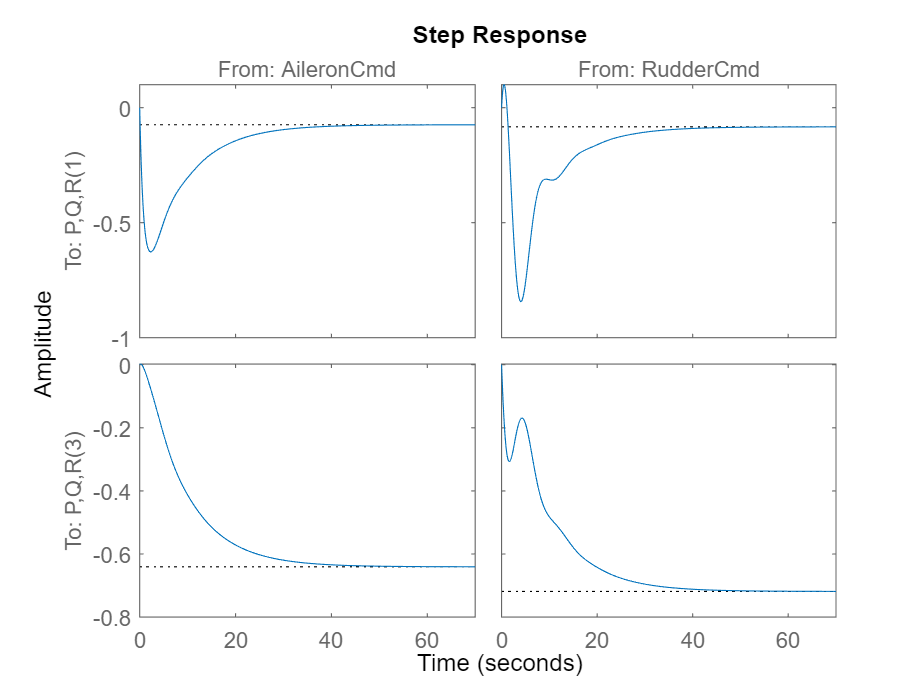

stepplot(aircraft_sys_Lat([1,3], [1,3]))

**Solve Characteristic Equation (Lateral-Directional)**


$$\lambda_{dr} =\zeta_{dr} \;\omega_{n_{dr} } \pm i\omega_{n_{dr} } \;\sqrt{1-\zeta_{dr}^2 }$$
   

**Dutch Roll **Damping Ratio: $\zeta_{sp} =\sqrt{\frac{1}{1+\frac{\omega_{dr} }{\eta_{dr} }}}$    Dutch Roll Undamped Natural Frequency: $\omega_{n_{dr} } =-\frac{\eta_{dr} }{\zeta_{dr} }$    Time to Double: $T_{2_{sp} } =\frac{\ln \left(2\right)}{-\zeta_{dr\;} \omega_{dr} }$

**Spiral Mode** Time Constant: $\tau_s =-\frac{1}{\lambda_s }$,    Time to Double Spiral Mode Amplitude: ${T_2 }_s =-\ln \left(2\right)\;\tau_s$

**Roll Mode** Time Constant: $\tau_r =-\frac{1}{\lambda_r }$,    Time to Double Roll Mode Amplitude: ${T_2 }_r =-\ln \left(2\right)\;\tau_r$

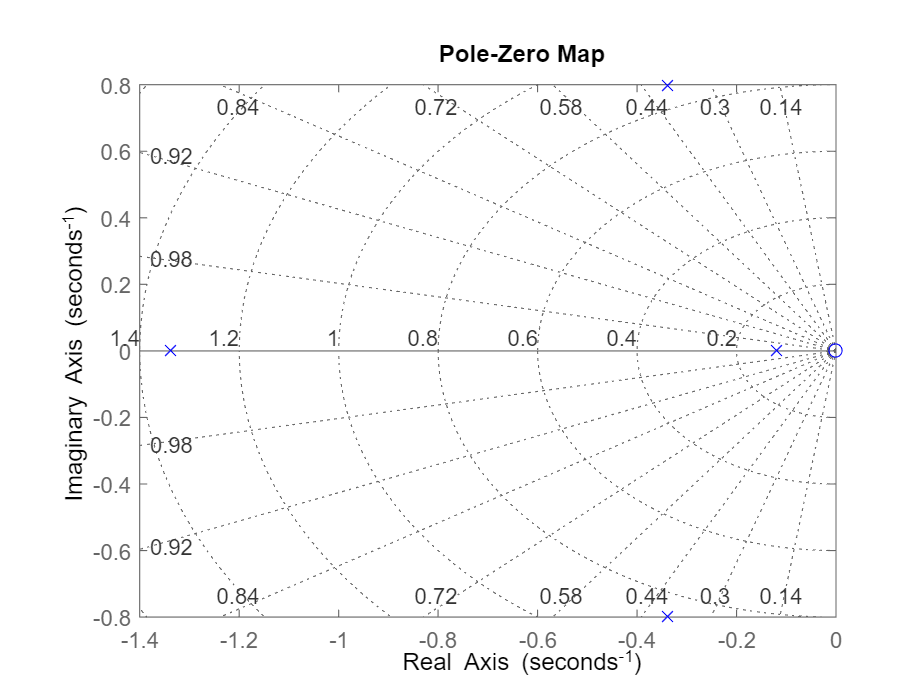

pzplot(aircraft_sys_Lat,'b'); 
grid on;

eigen_A_lat = eig(aircraft_sys_Lat);

The complex conjugate pair is the dutch roll mode. The real root with smaller magnitude is the spiral mode, and the remaining real root is the rolling mode.

dutch_roll = eigen_A_lat(2:3)

dutch_roll =   -0.3386 + 0.7980i
  -0.3386 - 0.7980i


dutchRoll_zeta = sqrt(1/(1+(imag(dutch_roll(1))/real(dutch_roll(1)))^2));
dutchRoll_omega_n = -real(dutch_roll(1))/dutchRoll_zeta;
dutchRoll_T2 = log(2)/(-dutchRoll_zeta * dutchRoll_omega_n);
fprintf(['dutch roll damping ratio = %f\n' ...
         'dutch roll undamped natural frequency = %f (rad/s)\n'...
         'time to double dutch roll = %f (s)'],dutchRoll_zeta,dutchRoll_omega_n,dutchRoll_T2);

dutch roll damping ratio = 0.390605
dutch roll undamped natural frequency = 0.866861 (rad/s)
time to double dutch roll = -2.047097 (s)

spiral = eigen_A_lat(4)

spiral = -0.1192

spiral_tau = -1/spiral;
spiral_T2 = -log(2) * spiral_tau;
fprintf(['spiral mode time constant = %f (s)\n'...
        'time to double the spiral mode amplitude = %f (s)'],spiral_tau,spiral_T2);

spiral mode time constant = 8.392290 (s)
time to double the spiral mode amplitude = -5.817092 (s)

roll_mode = eigen_A_lat(1)

roll_mode = -1.3371

roll_tau = -1/roll_mode;
roll_T2 = -log(2) * roll_tau;
fprintf(['roll mode time constant = %f (s)\n'...
        'time to double the roll mode amplitude = %f (s)'],roll_tau,roll_T2);

roll mode time constant = 0.747886 (s)
time to double the roll mode amplitude = -0.518395 (s)

**Compare Dutch Roll, spiral, and roll Response**


$$f(t) = (\omega_{n}/\sqrt{1-\zeta^{2}}) e^{-\zeta{\omega}t}sin(\omega_{n}\sqrt{1-\zeta^{2}}t )$$


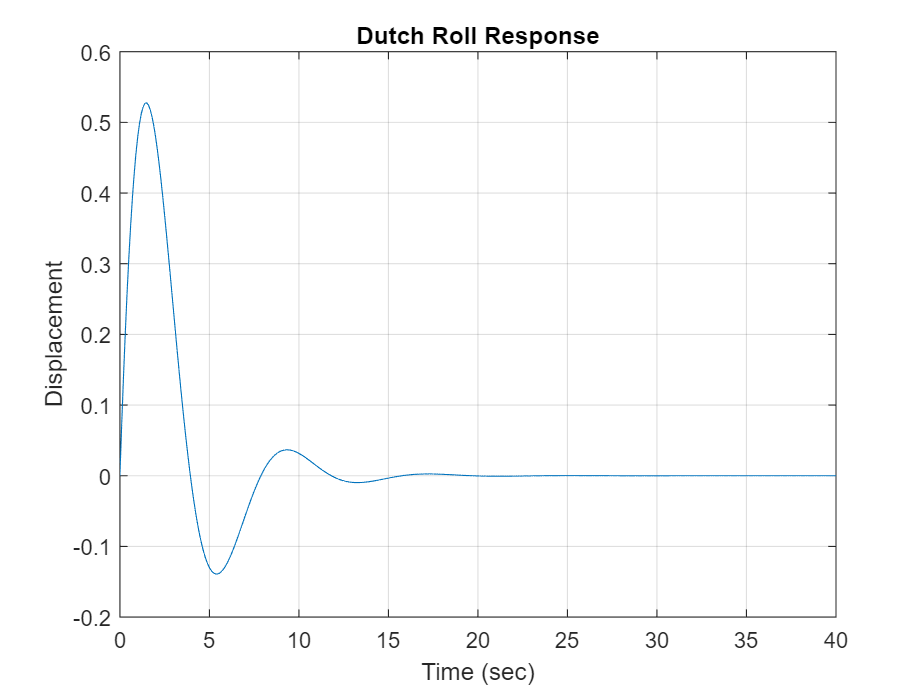

t = 0:.1:40;
figure;
plot(t, dutchRoll_omega_n/sqrt(1-dutchRoll_zeta^2).*exp(-dutchRoll_zeta*dutchRoll_omega_n*t).*sin(dutchRoll_omega_n*sqrt(1-dutchRoll_zeta^2)*t))
ylabel('Displacement'); xlabel('Time (sec)'); title('Dutch Roll Response'); grid on;


$$f\left(t\right)=\left(\frac{1}{\tau_r }\right)e^{-\frac{t}{\tau_r }}$$


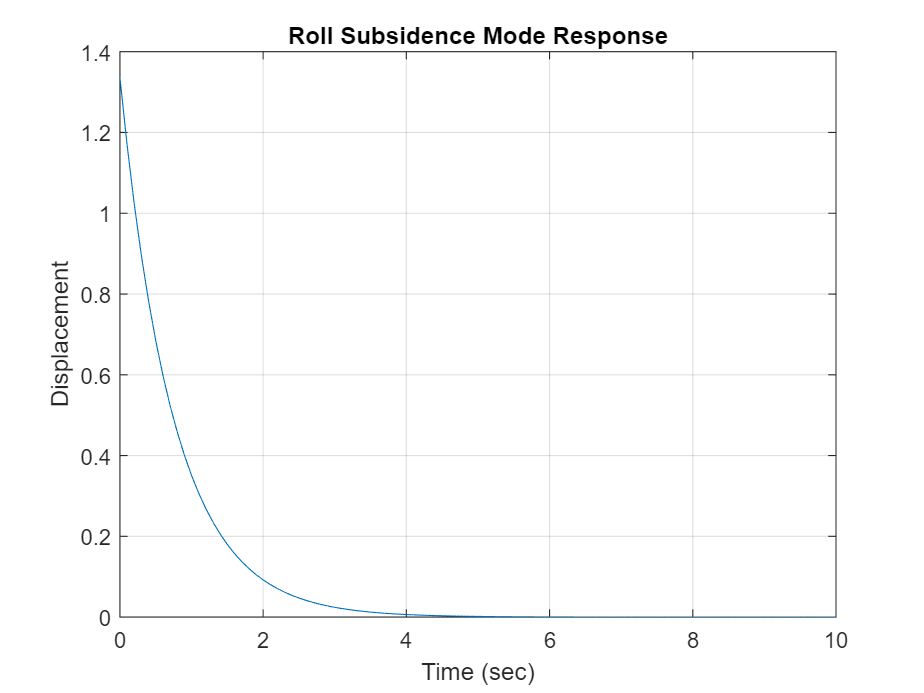

t = 0:.1:10;
figure;
plot(t, 1/roll_tau * exp(-t/roll_tau))
ylabel('Displacement'); xlabel('Time (sec)'); title('Roll Subsidence Mode Response'); grid on;

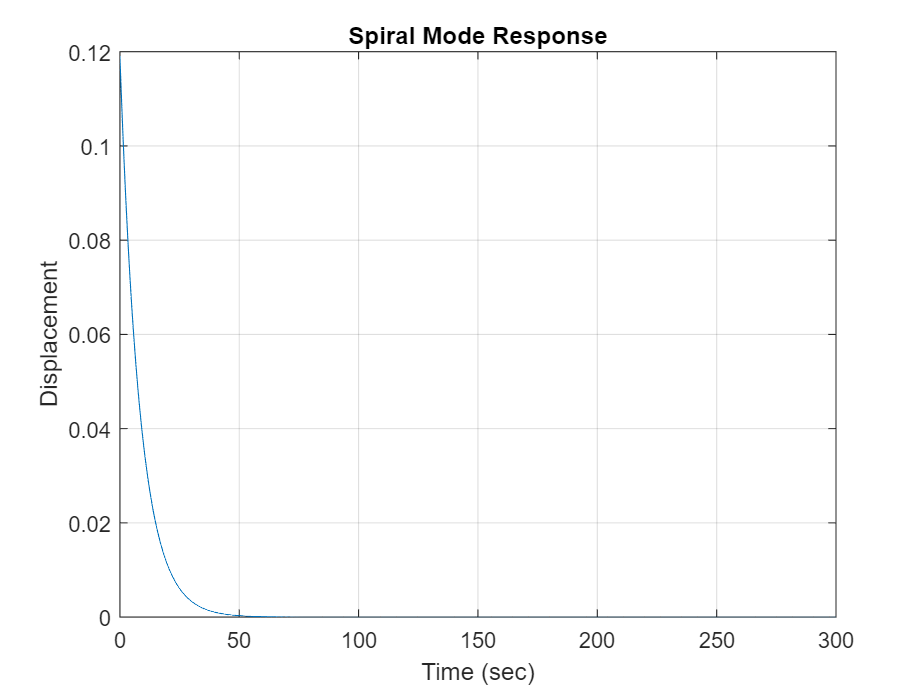

t = 0:.1:300;
figure;
plot(t, 1/spiral_tau * exp(-t/spiral_tau))
ylabel('Displacement'); xlabel('Time (sec)'); title('Spiral Mode Response'); grid on;

## Local Functions

function Lat_decimal_deg = LatDeg(deg,min,sec)

    Lat_decimal_deg = deg + min/60 + sec/3600;
end

function Lon_decimal_deg = LonDeg(deg,min,sec)

    Lon_decimal_deg = -deg - min/60 - sec/3600;
end